# Demonstration of structure-based superresolution data refinement method used in the Single Molecule Localization Challenge

## Data overview

The data itself is in the form of superresolution images, which show a few molecules of the fluorophores in the samples lighting up in any given acquisition. You collect thousands of such images and then find out the exact location of each of those molecules, so that we build a full superresolution image of the sample. Lets read the data:

% load images; these images come from the 
% Single Molecule Localization Microscopy Challenge 2016 
% hosted by a group in EPFL Switzerland. 
% They're simulated images and are made as acquired by 
% different microscopy modalities. We're going to load 
% data that is simulated for a "biplane imaging" method
% where the microscope acquires two images of the sample 
% at a time, at different focal points. This allows better
% calculation of the 3D location of the point sources.
nimages = 500;
nplanes = 2;
for imagecounter=nimages:-1:1
    for planecounter = 1:nplanes
        ims(:,:,planecounter,imagecounter) = ...
        imread(['..\Sample-Data-MUM\ImageFiles\Series',num2str(planecounter),...
        '\s',num2str(planecounter),'_',num2str(imagecounter),'.tif']);
    end
end
disp('Finished reading images..');

Finished reading images..


Here's how the raw data looks:

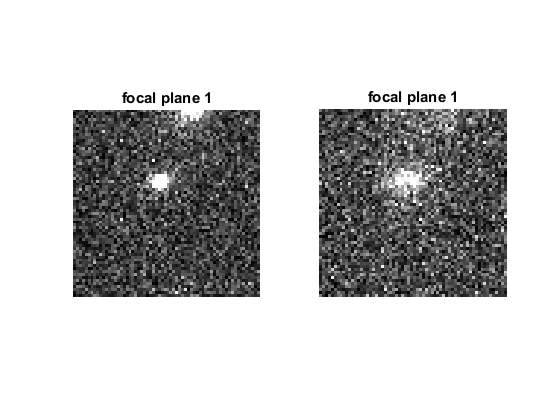

imagetolookat = 200;
subplot(1,2,1);
imshow(imadjust(ims(:,:,1,imagetolookat))); 
title('focal plane 1');
subplot(1,2,2);
imshow(imadjust(ims(:,:,2,imagetolookat)));
title('focal plane 2');

Here we see one point source in the middle of the image lighting up in boht the focal plane images (its slightly more blurred in the second image and thats the kind of information that allows us to calculate the 3D location of the point source). We then just look at thousands of images like this:

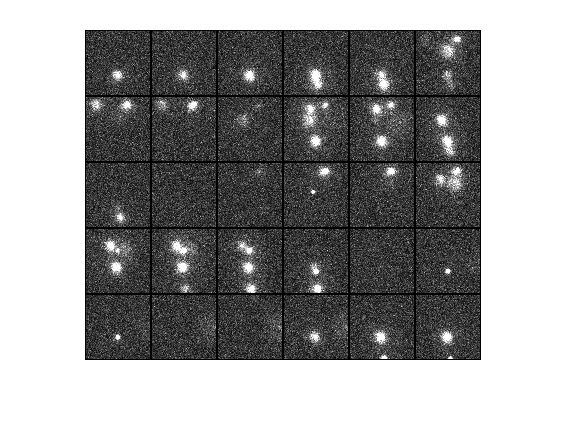

figure;mh = montage(padarray(ims(:,:,1,1:30),[1 1 0 0],100)); imshow(imadjust(get(mh,'cdata')));

Skipping over the steps of the processing, let's load the data that was obtained after the best efforts to identify the 3D location of each individual point source independently:

originaldata = readtable('final_original.csv');
groundtruth = readtable('mt0.n2.ld.bp.activations.csv');

disp(groundtruth(1:10,:));

    Ground_truth    frame    xnano     ynano     znano     intensity
    ____________    _____    ______    ______    ______    _________

     1               9039    43.325    839.83     340.7    267.35   
     2               9040    43.325    839.83     340.7    29.546   
     3              15342    39.005     850.2    331.86    420.77   
     4              15343    39.005     850.2    331.86    112.39   
     5              12283    56.375    868.42    333.77    56.924   
     6              13262    57.984    875.28    339.46    22.299   
     7              13263    57.984    875.28    339.46    194.74   
     8              13265    57.984    875.28    339.46    108.82   
     9               4084    69.829     859.5    340.35    105.75   
    10              19336    67.588 

disp(originaldata(1:10,:));

    Var1     Var2      Var3      Var4       Var5     Var6     Var7     Var8
    ____    ______    ______    _______    ______    ____    ______    ____

     1        5452    2811.8     193.68    8215.9    3000    104.24    1   
     2      5417.3    2862.1     193.68    5880.6    3000    102.72    1   
     3      5422.8    2872.3     193.68     10450    3000    142.54    1   
     4        5420    2852.4     193.68     15634    3000    119.22    1   
     5      5430.5    2853.6     193.68      6591    3000    134.48    1   
     6      6035.6    3305.5     173.31     10067    3000    125.82    1   
     9      2018.8    3823.4     112.76    6958.6    3000    109.43    1   
    10        2030    3861.7     112.76    

xvals = originaldata.Var2;
yvals = originaldata.Var3;
zvals = originaldata.Var4;

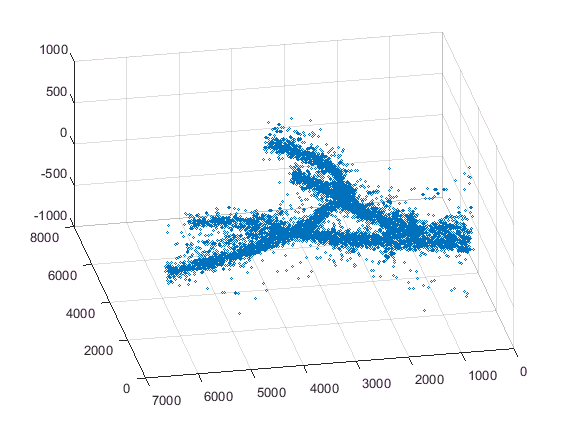

% this is our calculated values of the point sources
scatter3(xvals,yvals,zvals,1); view([-101 43])

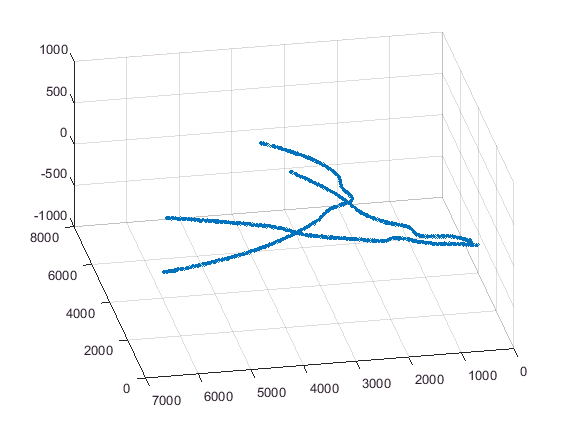

% this is the ground truth given by the competition
scatter3(groundtruth.xnano,groundtruth.ynano,groundtruth.znano,1); view([-101 43])

So we can see that our calculated data is a long ways from the ground truth. 

## Using underlying biological structure information to decrease the noise in the estimates

The ground truth image shows that the reconstructed super-resolution data is that of "microtubules" long thin strands of proteins that form a network inside cells. We know some basic properties of these microtubules - they're a few tens of nanometers theick, hollow cylinders, and while bendable cannot make sharp turns. The data shows that there are three microtubules in the image, so if we can "assign" ech of the identified point sources to one microtubule, we can then use the underlying structure information to "smooth" them. 

But, there are 

size(originaldata,1)

ans = 17951

points we have to assign and there are regions in the reconstruction that are a bit too confusing:

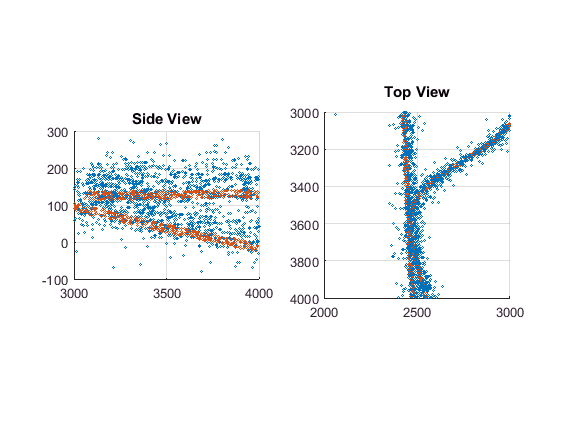

subplot(1,2,1);
hold off;scatter3(xvals,yvals,zvals,1);
hold on; scatter3(groundtruth.xnano,groundtruth.ynano,groundtruth.znano,1);
axis([3000 4000 2000 3000 -100 300]); daspect([1 1 0.5]);view(0,0); 
title('Side View');
subplot(1,2,2);
hold off;scatter3(xvals,yvals,zvals,1);
hold on; scatter3(groundtruth.xnano,groundtruth.ynano,groundtruth.znano,1);
axis([3000 4000 2000 3000 -100 300]); daspect([1 1 0.5]);view(90,90); 
title('Top View');

## Using clustering and manual assignment to identify the tubule structure each point source belongs to

One way to simplify the data would be to cluster the data. K-means clustering might be a good idea:

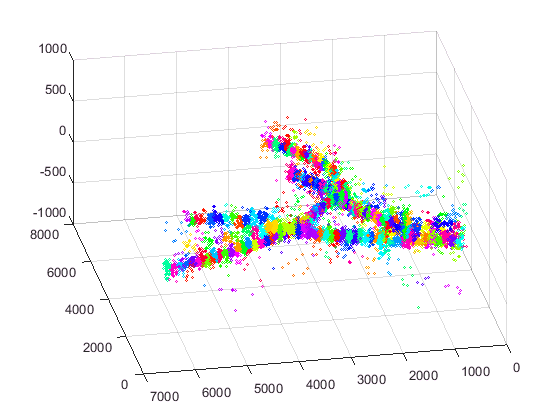

rng('default'); % want it to be repeatable
nclusters = 300;
[idx,c] = kmeans([xvals yvals zvals],nclusters);

% lets plot the clusters
figure
cmap = hsv(nclusters); % generate a colormap of hsv colors for each cluster
rr = randperm( max(idx(:))); 
% randomly assign each cluster a color from this spectrum 
% (makes it easier to see the edges)
for ii=1:numel(rr)
    i = rr(ii);
    scatter3(xvals(idx==i),...
        yvals(idx==i),...
        zvals(idx==i),1,cmap(ii,:));
    hold on;
    ncomps(i) = sum(idx==i);
end
corig = c;
view(-101,43);

Now we need to assign each of these clusters to one tubule. To do that, we first show a plot of the cluster centroids so that they can be manually assigned as a first step.

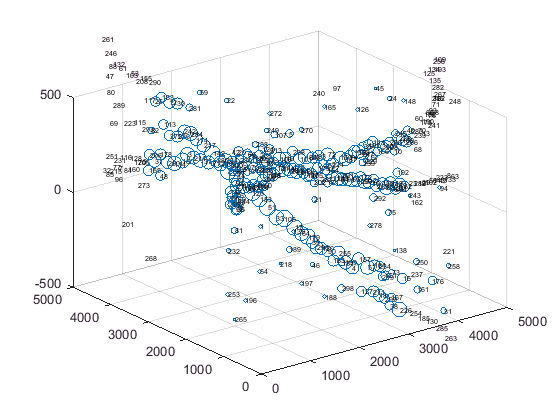

    cla
    hold off
    scatter3(corig(:,1),corig(:,2),corig(:,3),(ncomps))
    for j=1:size(corig,1)

             text(corig(j,1),corig(j,2),corig(j,3),num2str(j),'fontsize',5);
        
    end 
    axis([0000 5000 0000 5000 -500 500]);

At least for the competition, these clusters were manually assigned one tubule each (now you know why the random number generator was set to "default" above :) ). 

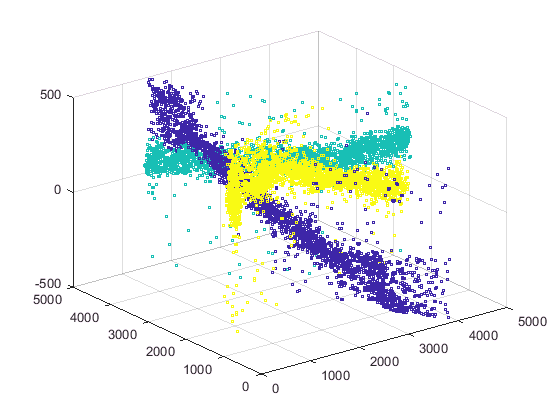


    figure;
    % manual assignment of each of the clusters above to a particular tubule
    % takes an hour if the data is good.
    tubules = {...
        [201 223 61 132 289 88 88 69 47 246 261 103 53 208 115 293 117 155 290 ...
        82 25 183 113 279 12 30 ...
        236 30 242 281 284 59 174 217 142 210 277 87 44 131 123 153 51 33 271 ...
        189 105 17 64 197 179 39 ...
        296 120 188 90 163 255 298 291 199 4 157 127 229 57 278 211 164 18 234 ...
        219 299 151 38 73 167 104 226 15 254 250 243 161 185 130 176 285 94 31 ...
        263 258 21],...
        [32 85 215 251 77 231 7 116 84 160 128 96 170 205 273 158 206 37 48 178 ...
        260 114 180 3 214 137 177 80 ...
        9 268 280 264 232 22 227 20 207 78 262 288 1 203 235 52 213 272 209 106 ...
        19 238 186 101 184 26 240 83  ...
        72 252 224 97 46 150 187 74 152 168 126 247 259 35 191 67 111 45 166 300 ...
        108 24 286 245 228 10 100 266 ...
        148 40 283 239 60 68 70 175 190 13 182 86 241 76 93 28 216 71 282 122 ...
        267 36 193 109 256 135 134 125 ...
        241 237],...      
        [221 63 248 8 133 43 233 143 56 102 29 89 212 162 23 62 49 138 192 ...
        149 204 222 292 156 75 269 2 119 ...
        99 172 129 65 91 34 145 112 154 171 287 165 173 202 275 140 198 141 ...
        41 244 136 118 121 181 5 139 270 ...
        107 58 146 79 50 295 249 124 220 14 274 225 257 95 110 194 66 230 ...
        276 27 218 16 54 196 200 297 147 294 ...
        98 144 55 81 159 92 11 195 42 265 253 169 6]};
    belongstoatubule = ismember(idx,cell2mat(tubules));
    clustertubuleids = zeros(size(c,1),1);
    for j=1:numel(tubules)
        tubuleidentitymat(:,j) = ismember(idx,tubules{j});
        clustertubuleids(ismember(1:size(c,1),tubules{j})) = j;
    end
    for j=1:size(tubuleidentitymat,1)
        this = find(tubuleidentitymat(j,:),1,'first');
        if isempty(this)
            tubuleidentity(j) = 0;
        else
            tubuleidentity(j) = this;
        end
    end
    tubuleid = xvals*0;
    for i=1:numel(xvals)
        if belongstoatubule(i)
            tubuleid(i) = tubuleidentity(i);
        else            
            tubuleid(i) = 0;
        end        
    end
    scatter3(xvals,yvals,zvals,3,tubuleid);
    axis([0000 5000 0000 5000 -500 500]);   

## Fitting the original data to smooth it out

So we now have each of the 17000 odd point sources assigned to a tubule. Now we can go ahead and fit them to a spline :)

hold off

zvalscorrected = zvals;
xvalscorrected = xvals;
yvalscorrected = yvals;
zvalsfitted = zvals;
xvalsfitted = xvals;
yvalsfitted = yvals;
for j=1:numel(tubules)
    % we do this seperately for each tubule. First we get
    % all the point sources belonging to the tubule.
    xb = xvals(tubuleid==j);
    yb = yvals(tubuleid==j);
    zb = zvals(tubuleid==j)-12.76;
    % -12.76 is an offset caused due to our Z-localization algorithm.        
    
    % we cluster the data again within this tubule. 
    nc = 200;
    [idx2{j},clustercenters{j}] = kmeans([xb yb ],nc);
    rr = randperm( max(idx2{j}(:)));
    zbcorrected = zb;
    xbcorrected = xb;
    ybcorrected = yb;
    for ii=1:numel(rr)
        i = rr(ii);
        % for each of these tubule-specific clusters, we find the median 
        % x y and z values and assign them to all the members temporarily.        
        zbthis = zb(idx2{j}==i);
        zbthis = (zbthis*0)+median(zbthis);
        zbcorrected(idx2{j}==i) = zbthis;
        xbcorrected(idx2{j}==i) = 0*zbthis+median(xb(idx2{j}==i));
        ybcorrected(idx2{j}==i) = 0*zbthis+median(yb(idx2{j}==i));  
        ncomps(i) = sum(idx2{j}==i);
    end
    zvalscorrected(tubuleid==j) = zbcorrected;
    yvalscorrected(tubuleid==j) = ybcorrected;
    xvalscorrected(tubuleid==j) = xbcorrected;
    % The assigning of the median value for each of the cluster makes the 
    % image look step-wise. We "smooth" out by fitting the data to a spline
    % model, just for the z data. 
    fitobject = fit([xb,yb],zbcorrected,'lowess','span',0.30);
    zbfitted =fitobject(xb,yb);
    zvalsfitted(tubuleid==j) = zbfitted;    
end
% we don't want to use the k-means averaged data for x and y estimates 
% all the time, only when the x and y estimates are off from the k-means
% center by 40 nanometers which means its probably a bad estimation.
% so we switch back the x and y estimates to the original estimates when 
% they are closer than that.
switchback = abs(xvalscorrected-xvals)+abs(yvalscorrected-yvals)<40;
xvalscorrected(switchback)=xvals(switchback);
yvalscorrected(switchback)=yvals(switchback);

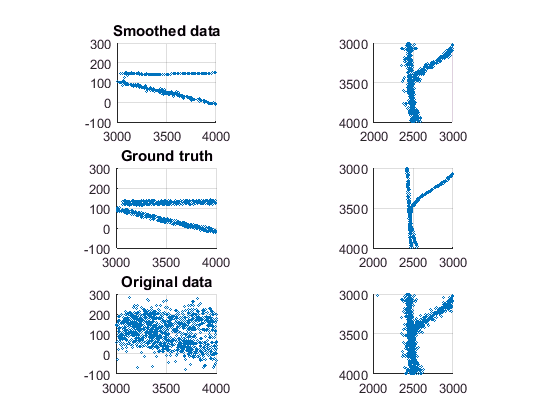


% now plot it
subplot(3,2,1);
hold off;
scatter3(xvalscorrected,yvalscorrected,zvalsfitted,1);
axis([3000 4000 2000 3000 -100 300]); daspect([1 1 0.5]);view(0,0); 
title('Smoothed data');
subplot(3,2,3);
scatter3(groundtruth.xnano,groundtruth.ynano,groundtruth.znano,1);
axis([3000 4000 2000 3000 -100 300]); daspect([1 1 0.5]);view(0,0); 
title('Ground truth');
subplot(3,2,5);
scatter3(xvals,yvals,zvals,1);
axis([3000 4000 2000 3000 -100 300]); daspect([1 1 0.5]);view(0,0); 
title('Original data');
subplot(3,2,2);
hold off;
scatter3(xvalscorrected,yvalscorrected,zvalsfitted,1);
axis([3000 4000 2000 3000 -100 300]); daspect([1 1 0.5]);view(90,90)
subplot(3,2,4);
scatter3(groundtruth.xnano,groundtruth.ynano,groundtruth.znano,1);
axis([3000 4000 2000 3000 -100 300]); daspect([1 1 0.5]);view(90,90); 
subplot(3,2,6);
scatter3(xvals,yvals,zvals,1);
axis([3000 4000 2000 3000 -100 300]); daspect([1 1 0.5]);view(90,90); 

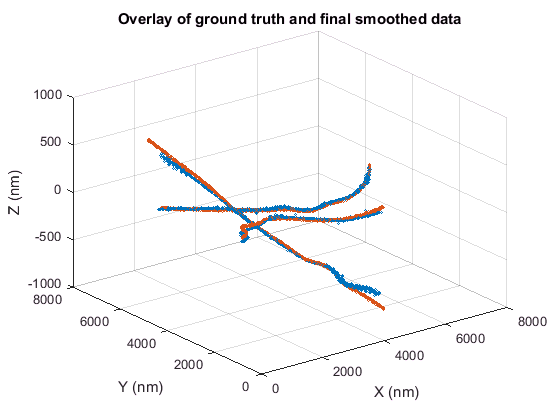

figure
hold off;scatter3(xvalscorrected,yvalscorrected,zvalsfitted,1);
hold on;
scatter3(groundtruth.xnano,groundtruth.ynano,groundtruth.znano,1);
title('Overlay of ground truth and final smoothed data');
ylabel('Y (nm)');xlabel('X (nm)'); zlabel('Z (nm)');